clear all; close all;

## 入力

% ファイル読み込み
[cleanOrig, fsClean] = audioread("speech.wav");
cleanOrig = cleanOrig(:,1);

[irOrig, fsIr] = audioread("ir_concerthall.wav");
irOrig = irOrig(:,1);

% ダウンサンプリング
targetFs = 8000;
fs = targetFs;
cleanShort = resample(cleanOrig, targetFs, fsClean);
irShort = resample(irOrig, targetFs, fsIr);

% RIR調整
[~, max_idx] = max(abs(irShort));
pre_pad = 0; 
cut_start = max(1, max_idx - pre_pad);
irShort = irShort(cut_start:end);

decay_constant = 0.0005; 
t_ir = (0:length(irShort)-1)';
irEnv = exp(-decay_constant * t_ir);
ir_scaled = irShort .* irEnv;

threshold = 1e-4;
last_idx = find(abs(ir_scaled) > threshold, 1, 'last');
if isempty(last_idx), last_idx = length(ir_scaled); end
ir_final = ir_scaled(1:last_idx);
irShort = ir_final / max(abs(ir_final));

% 信号カット
N_sec = 20;
N_samples = min(length(cleanShort), N_sec * fs);
data_clean = cleanShort(1:N_samples); % 評価で使うクリーン音源本体

% 残響音声生成
data_reverb_raw = conv(data_clean, irShort, 'full');

% STFT
F = DGTtool('windowLength', 512, 'windowShift', 64);
F.makeWindowTight;

diffWin deleted
dual window checked


X_temp = F(data_reverb_raw);
data_reverb = F.pinv(X_temp);

index computed (OLA)


N_all = length(data_reverb);

% 長さ合わせ
s_clean_padded = zeros(N_all, 1);
s_clean_padded(1:length(data_clean)) = data_clean;

% 正規化
normalizeConst = max(abs(data_reverb));
data_reverb = data_reverb / normalizeConst;
s_clean_padded = s_clean_padded / normalizeConst;

% STFT完
X_obs = F(data_reverb);       
cleanRefDGT = F(s_clean_padded); 
% [Fq, T] = size(X_obs);

## 手法 1: Standard WPE

初期化：


$$\hat{\rho}_{n,f}^2=\max\{|x_{n,f}|^2, \varepsilon_f\}$$


更新式：


$$\hat{\bar{c}}_f={\Big(\sum_{n}\frac{\bar x_{n-D',f}\bar x_{n-D',f}^{T}}{\hat\rho_{n,f}^2}\Big)}^+{\Big(\sum_{n}\frac{\bar x_{n-D',f}x_{n,f}^{(1)}}{\hat\rho_{n,f}^2}\Big)}$$



$$\hat{d}_{n,f}=x_{n,f}^{(1)}-\hat{\bar{c}}_f^{*{T}}\bar x_{n-D',f}$$



$$\hat{\rho}_{n,f}^2=\max\{|\hat d_{n,f}|^2, \varepsilon_f\}$$


fprintf('Running Method 1: Standard WPE...\n');

Running Method 1: Standard WPE...


% パラメータ設定
L_c_ms = 280;
D_ms = 32;
frame_duration_sec = F.shift / fs;
L_c = round((L_c_ms * 1e-3) / frame_duration_sec);
D = round((D_ms * 1e-3) / frame_duration_sec);
[Fq, T] = size(X_obs);

% 初期化
d_wpe = X_obs; % 観測信号で初期化

tic
% 周波数ループ
for f = 1 : Fq
    % 周波数 f の観測信号
    x_f = X_obs(f, :);
    
    % 周波数 f の遅延信号行列
    X_f = zeros(L_c, T);
    for l = 1:L_c
        X_f(l, D+l:T) = x_f(1 : T-D-l+1);
    end
    
    % εと分散の初期化
    eps_wpe = max(abs(x_f).^2) * 10^-5;
    var_est = max(abs(x_f).^2, eps_wpe);
    
    for iter = 1:10
        % 時変分散の逆数
        W = 1 ./ var_est; 
        
        % 共分散行列と相関ベクトル
        X_weighted = X_f .* W; 
        Phi = X_weighted * X_f'; Phi = Phi + 10^-5 * trace(Phi) * eye(L_c);
        phi = X_weighted * x_f';
        
        % 式部分：フィルタ・残響除去信号・時変分散の更新
        c_f = pinv(Phi) * phi;
        d_wpe(f, :) = x_f - c_f' * X_f;
        var_est = max(abs(d_wpe(f, :)).^2, eps_wpe);
    end
end
toc

経過時間は 9.119766 秒です。


out1 = F.pinv(d_wpe);
% F.plot(buffer(data_clean, length(out1)));
% F.plot(data_reverb);
% F.plot(out1);

## 手法2: Oracle WPE

初期化：


$${\rho}_{n,f}^2=\max\{|d_{n,f}|^2, \varepsilon_f\}$$


更新式：


$$\hat{\bar{c}}_f={\Big(\sum_{n}\frac{\bar x_{n-D',f}\bar x_{n-D',f}^{T}}{\rho_{n,f}^2}\Big)}^+{\Big(\sum_{n}\frac{\bar x_{n-D',f}x_{n,f}^{(1)}}{\rho_{n,f}^2}\Big)}$$



$$\hat{d}_{n,f}=x_{n,f}^{(1)}-\hat{\bar{c}}_f^{*{T}}\bar x_{n-D',f}$$


fprintf('Running Method 2: Oracle WPE...\n');

Running Method 2: Oracle WPE...


% パラメータ設定
L_c_ms = 280;
D_ms = 32;
frame_duration_sec = F.shift / fs;
L_c = round((L_c_ms * 1e-3) / frame_duration_sec);
D = round((D_ms * 1e-3) / frame_duration_sec);
[Fq, T] = size(X_obs);

% 初期化
d_owpe = zeros(Fq, T);

tic
% 周波数ループ
for f = 1 : Fq
    % 周波数 f の観測信号＆クリーン信号
    x_f = X_obs(f, :);
    clean_f = cleanRefDGT(f, :);
    
    % 周波数 f の遅延信号行列
    X_f = zeros(L_c, T);
    for l = 1:L_c
        X_f(l, D+l:T) = x_f(1 : T-D-l+1);
    end
    
    % Oracle時変分散
    eps_wpe = max(abs(clean_f).^2) * 10^-5;
    var_oracle = max(abs(clean_f).^2, eps_wpe);

    % 時変分散の逆数
    W = 1 ./ var_oracle; 
    
    % 共分散行列と相関ベクトル
    X_weighted = X_f .* W; 
    Phi = X_weighted * X_f'; Phi = Phi + 10^-5 * trace(Phi) * eye(L_c);
    phi = X_weighted * x_f';
    
    % 式部分：フィルタ・残響除去信号の更新
    c_f = pinv(Phi) * phi;
    d_owpe(f, :) = x_f - c_f' * X_f;
end
toc

経過時間は 1.793592 秒です。



out2 = F.pinv(d_owpe);
% F.plot(buffer(data_clean, length(out2)));
% F.plot(data_reverb);
% F.plot(out2);

## 手法3: 提案法

使用するアルゴリズム（PDS）

問題：$\text{minimize}_{x\in \mathbb{R}^N} \quad f(x)+g(Lx)+h(x)$

Algorithm 2 in "Playing with Duality" 


$$p = \mathrm{prox}_{\tau f}(x-\tau (\nabla h(x) +L^Tv))\\
q = \mathrm{prox}_{\sigma g^*}(v+\sigma L(2p-x))\\
x = x + \rho(p - x)\\
v = v + \rho(q - v)$$


今回の最小化問題

問題：$\text{minimize}_{{x}} \quad
 \|\mathcal{F}({Yx}) \|_{{w_{s}},1} + \frac{\beta}{2} \|{x} \|_{{w_{x}},2}^2 + \iota_C({x})$


$$$f({x}) = \iota_C({x})$$$



$$$g({Lx}) = \|\mathcal{F}({Yx})\|_{{w_s},1}$$$



$$$h({x}) = \frac{\beta}{2} \|{x}\|_{{w_x},2}^2$$$


（ここまでで実装可能なので以下はオマケ．代入してみたもの）


$${p}_n = P_C \left( {x}_n - \tau \left( \beta ({w}_x \odot {x}_n) + {L}^{T} {v}_n \right) \right)\\
{u}_n = {v}_n + \sigma {L}(2{p}_n - {x}_n)\\
{q}_n = {u}_n - \sigma \left( \text{prox}_{\sigma^{-1}\|\cdot\|_{{w_{s}},1}} \left( \frac{{u}_n}{\sigma} \right) \right)\\
{x}_{n+1} = {x}_n + \rho ({p}_n - {x}_n) \\
{v}_{n+1} = {v}_n + \rho ({q}_n - {v}_n)$$


fprintf('Running Method 3: Proposed Algorithm...\n');

Running Method 3: Proposed Algorithm...



N_fft = length(data_clean) + N_all - 1; % 線形畳み込みサイズ

% アルゴリズムパラメータ
beta  = 0.01;
sigma = 0.9;
tauRatioFromMax = 0.9; % 0 to 1
rhoRatioFromMax = 1; % 0 to 1 
maxIter = 1000;
D_ms = 8; 
delayOfFilter = round(D_ms * 1e-3 * fs); % 直接音保護区間

% ステップサイズ
tau = 1/(sigma + beta/2); % Warning: ||L|| = 1, max|w_a| = 1
tau = tauRatioFromMax * tau;
delta = 2 - beta/(1/tau - sigma)/2; % Warning: ||L|| = 1, max|w_a| = 1
rho = rhoRatioFromMax * delta; % rho <= delta

% 重み
S = abs(cleanRefDGT);
env = smoothdata(S, 'lowess', 30);
S_norm = S ./ (max(env, 1e-2));

dataInFreqDom = fft(data_reverb, N_fft);
normalizeConst = max(abs(dataInFreqDom));
dataInFreqDom = dataInFreqDom / normalizeConst;

% 演算子・関数の設定
L  = @(v) F(ifft(dataInFreqDom .* fft(v, N_fft), 'symmetric'));
Lt = @(V) inv_linear_conv(V, dataInFreqDom, N_fft, N_all, F);

% 双対変数のサイズ取得
sample_V = L(zeros(N_all, 1));
[v_rows, v_cols] = size(sample_V);

paramW = 2;
w_tmp = 1 ./ (S_norm + 1e-1);
w_min = min(w_tmp, [], 'all');
w_base = max(0, w_tmp - paramW * w_min);

% 平均値パディング
weight_x = zeros(v_rows, v_cols);
cols_to_fill = min(size(w_base, 2), v_cols);
weight_x(:, 1:cols_to_fill) = w_base(:, 1:cols_to_fill);
if v_cols > cols_to_fill
    weight_x(:, cols_to_fill+1:end) = mean(w_base, 'all'); 
end

% % hann窓
% weight_a = hann(N_all) / max(hann(N_all));

% Gauss窓
alpha = 2.5; 
weight_a = gausswin(N_all, alpha) / max(gausswin(N_all, alpha));

% 正規化（最大値を1にする）
weight_a = weight_a / max(weight_a);

idx_protect = [2:delayOfFilter, N_all-delayOfFilter+1:N_all]; % 直接音・初期反射保護区間（遅延）
proxTauF = @(x) proj1and0(x, 1, idx_protect, normalizeConst);
proxSigG = @(v, s) proxL1(v, s, weight_x);
proxSigGconj = @(v) v - sigma * proxSigG(v/sigma, 1/sigma);
nablaH = @(x) beta * weight_a .* x;

x = zeros(N_all, 1);
x(1) = normalizeConst;
v = zeros(v_rows, v_cols);

% PDS
tic
for n = 1:maxIter
    p = proxTauF(x - tau * (nablaH(x) + Lt(v)));
    q = proxSigGconj(v + sigma * L(2*p - x));
    x = x + rho * (p - x);
    v = v + rho * (q - v);
end

index computed (OLA)


toc

経過時間は 380.153945 秒です。


% フィルタ中央部ゼロ埋め・スムージング
idx_start = 1 * round(length(x)/3);
idx_end   = 2 * round(length(x));
cut_width = idx_end - idx_start;

% フェードの長さ
fade_len = round(cut_width * 0.2); 
 
% 窓
fade_out = cos(linspace(0, pi/2, fade_len))'.^2;
% fade_in  = sin(linspace(0, pi/2, fade_len))'.^2;
% 
% フェードアウト
x(idx_start : idx_start + fade_len - 1) = x(idx_start : idx_start + fade_len - 1) .* fade_out;
% 中央部ゼロ
x(idx_start + fade_len : idx_end - fade_len) = 0;
% % フェードイン
% x(idx_end - fade_len + 1 : idx_end) = x(idx_end - fade_len + 1 : idx_end) .* fade_in;

% 出力
% x(1)=1;
% x(2:end)=0;
out3 = F.pinv(L(x));
out3question = conv(x,data_clean);
% F.plot(buffer(data_clean, length(out3)));
% F.plot(data_reverb);
% F.plot(out3);

## 評価

fprintf('\n--- Performance Evaluation (SDR) & Audio Export ---\n');


--- Performance Evaluation (SDR) & Audio Export ---



ref_sig = s_clean_padded(1:N_all);
outs = {out1(1:N_all), out2(1:N_all), out3(1:N_all)};
names = {'WPE', 'Oracle_WPE', 'Proposed_Algorithm'};

clean_save = ref_sig / max(abs(ref_sig));
audiowrite('0_Reference_Clean.wav', clean_save, fs);
fprintf('Saved: 0_Reference_Clean.wav\n');

Saved: 0_Reference_Clean.wav



reverb_save = data_reverb / max(abs(data_reverb));
audiowrite('1_Input_Reverb.wav', reverb_save, fs);
fprintf('Saved: 1_Input_Reverb.wav\n');

Saved: 1_Input_Reverb.wav


for i = 1:3
    sig_eval = outs{i};
    
    [sdr, ~, ~] = fast_bss_eval_sources(sig_eval', ref_sig');
    fprintf('%s: %.4f dB\n', names{i}, sdr);
    
    output_filename = sprintf('2_Result_%s.wav', names{i});
    out_save = sig_eval / max(abs(sig_eval));
    audiowrite(output_filename, out_save, fs);
    fprintf('  -> Saved: %s\n', output_filename);
end

WPE: 5.8866 dB


  -> Saved: 2_Result_WPE.wav


Oracle_WPE: 7.5051 dB


  -> Saved: 2_Result_Oracle_WPE.wav


Proposed_Algorithm: 11.0720 dB


  -> Saved: 2_Result_Proposed_Algorithm.wav


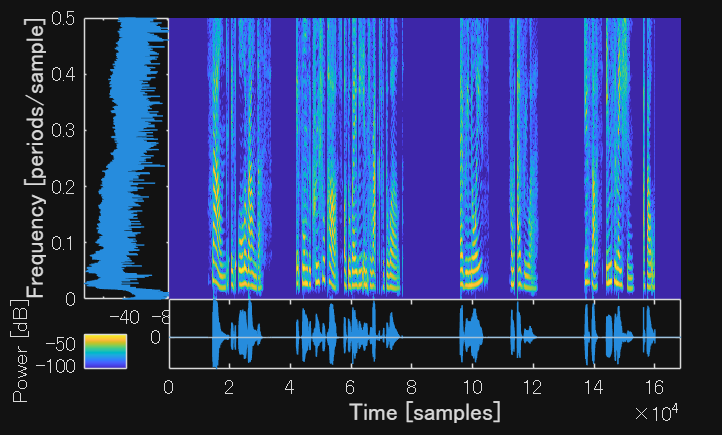


% スペクトログラム
F.plot(s_clean_padded);

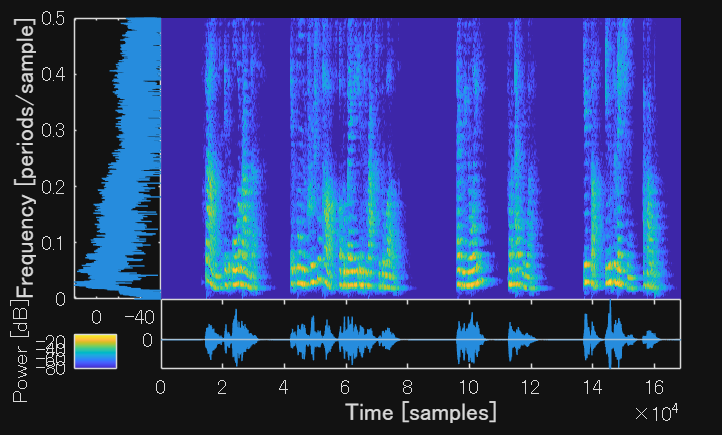

F.plot(data_reverb);

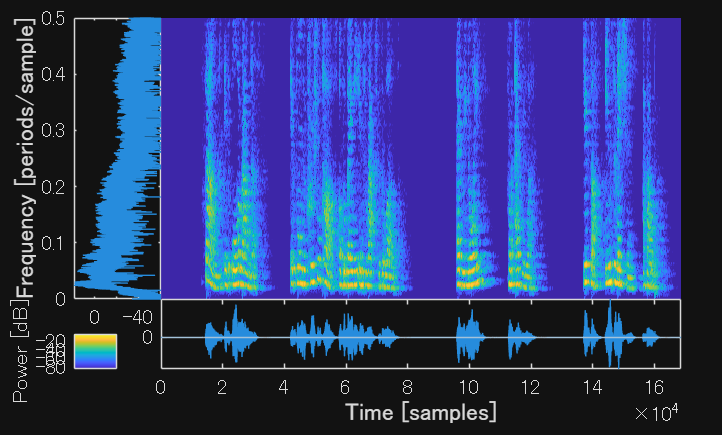

F.plot(out1(1:N_all));

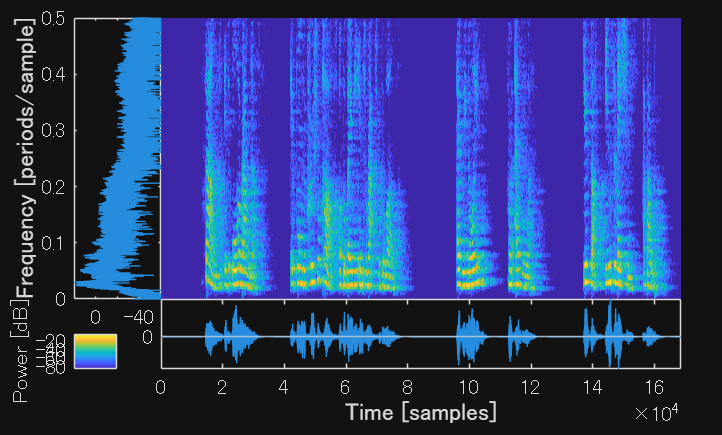

F.plot(out2(1:N_all));

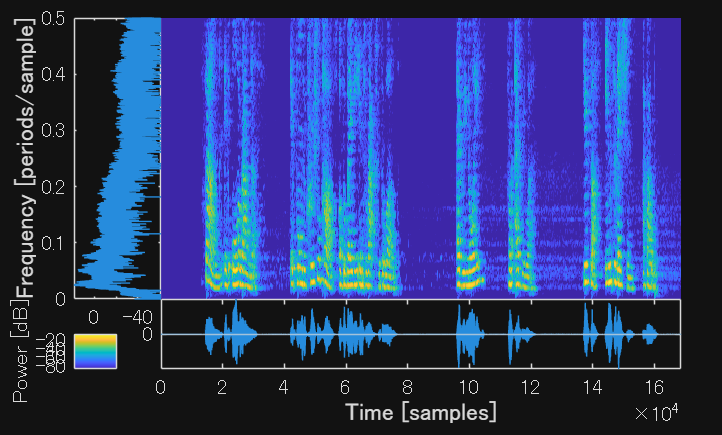

F.plot(out3(1:N_all));

Function 1: $\mathrm{prox}_{\lambda\|\cdot\|_1}$ (Section 6.5.2 of "Proximal Algorithms")

function x = proxL1(x, lambda, w)
x = max(0, 1 - lambda./abs(x./w)) .* x;
end

Function 2: Projection onto a lower-dimensional affine subspace

function x = proj1and0(x, idx1, idx0, peakAmp)
x(idx1) = peakAmp;
x(idx0) = 0;
end

function res = inv_linear_conv(V, H_freq, N_fft, target_len, F_op)
    % 1. 観測空間の信号を時間ドメインへ (F.H は V の随伴)
    v_time = F_op.H(V); 
    % 2. N_fft までゼロパディングしてFFT
    V_freq = fft(v_time, N_fft);
    % 3. フィルタの複素共役と乗算（相関演算）
    res_full = ifft(conj(H_freq) .* V_freq, 'symmetric');
    % 4. 先頭からターゲットの長さ(len_x)だけ切り出す (Pv^H に相当)
    res = res_full(1:target_len);
end